% Defining obstacles in the workspace
% For each obstacle, we also define the the zone of influence around it.

% Initializing array for storing the information for the obstacles 
% and the zone of influence around the obstacle
%--------------------------------------------------------------------------
% P:     stores the zone of influences for all the obstacles
% pgon:  stores the information for all the obstacles in the workspace
% P_r:   stores the parameters of the various zone of influence
%--------------------------------------------------------------------------
P = repmat(polyshape,1,4);
pgon = repmat(polyshape,1,4);
P_r = zeros(3,4);

% Defining the paramaters for various obstacles
% pgon(1): Square obstacle
pgon(1) = polyshape([3 3 4 4],[3 4 4 3]);
P(1) = influencePoly(3.5,3.5,2);
P_r(1,1) = 2;
P_r(1,2) = 3.5;
P_r(1,3) = 3.5;

% pgon(2): Triangular obstacle
pgon(2) = polyshape([3 4 4],[6 6 7]);
P(2) = influencePoly(11/3,19/3,1);
P_r(2,1) = 1;
P_r(2,2) = 20/3;
P_r(2,3) = 19/3;

% pgon(3): Circular obstacle
xc = 6;
yc = 6;
r = 1;
n = 100;
theta = (0:n-1)*(2*pi/n);
x = xc + r*cos(theta);
y = yc + r*sin(theta);
pgon(3)= polyshape(x,y);
P(3) = influencePoly(6,6,2);
P_r(3,1) = 2;
P_r(3,2) = 6;
P_r(3,3) = 6;

% pgon(4): Square obstacle
pgon(4) = polyshape([5 5 6 6],[3 4 4 3]);
P(4) = influencePoly(5.5,3.5,2);
P_r(4,1) = 2;
P_r(4,2) = 5.5;
P_r(4,3) = 3.5;

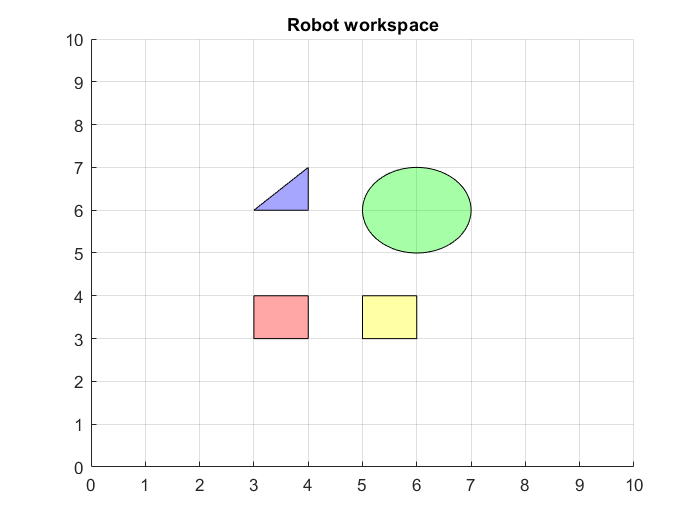

% Plotting the robot workspace
f1 = figure;
figure(f1)
axis([0 10 0 10])
title("Robot workspace")
hold on
grid on
plot(pgon(1),'Facecolor', 'r')
plot(pgon(2), 'Facecolor', 'b')
plot(pgon(3), 'Facecolor', 'g')
plot(pgon(4), 'Facecolor', 'y')

## Plotting autonomous paths for different values of neta and zeta

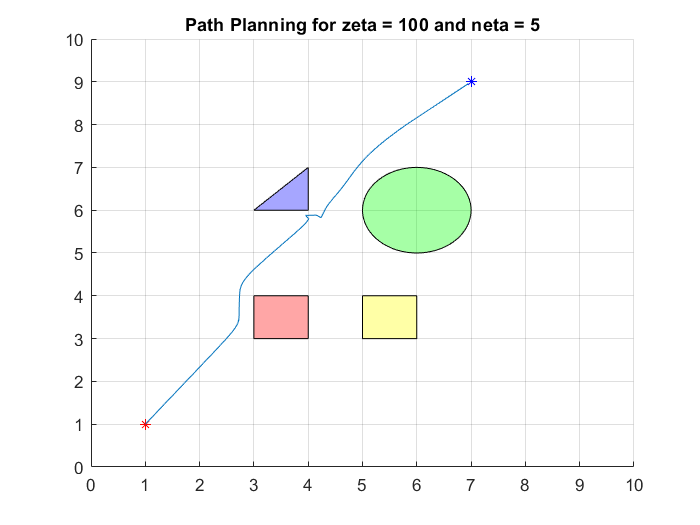

% Plot-1
% Defining the start and goal points and tuning constants for the 
% attractive and repulsive potential fields
start = [1,1];
goal = [7,9];
zeta = 100;
neta = 5;

computePath(pgon,P,P_r,start, goal,zeta,neta)

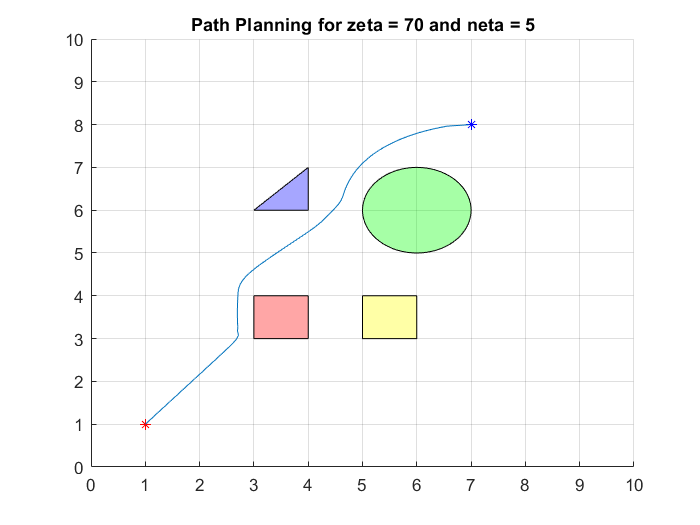

% Plot-2
% Defining the start and goal points and tuning constants for the 
% attractive and repulsive potential fields
start = [1,1];
goal = [7,8];
zeta = 70;
neta = 5;

computePath(pgon,P,P_r,start, goal,zeta,neta)

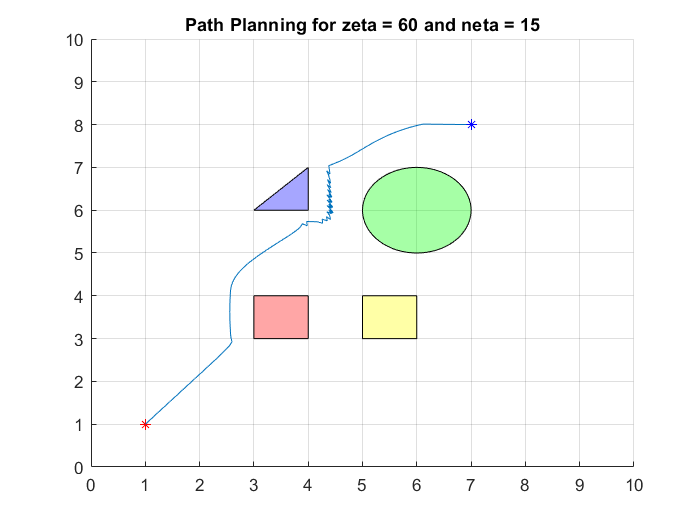

% Plot-3
% Defining the start and goal points and tuning constants for the 
% attractive and repulsive potential fields
start = [1,1];
goal = [7,8];
zeta = 60;
neta = 15;

computePath(pgon,P,P_r,start, goal,zeta,neta)

## Trapping the robot on local minima

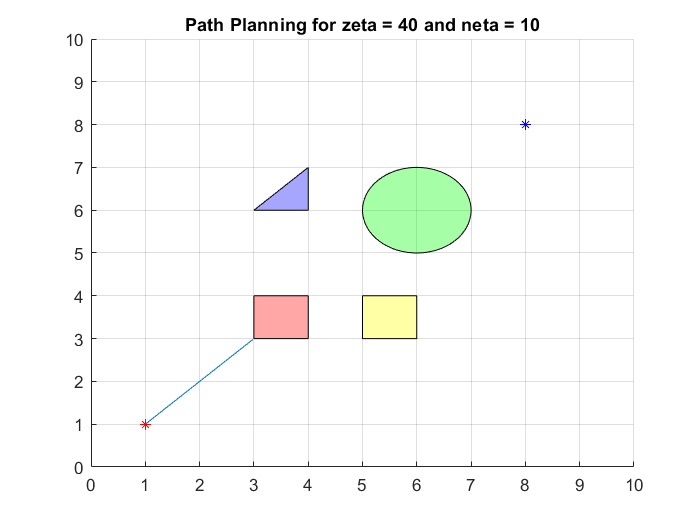

% Defining the start and goal points and tuning constants for the 
% attractive and repulsive potential fields
start = [1,1];
goal = [8,8];
zeta = 40;
neta = 10;

computePath(pgon,P,P_r,start, goal,zeta,neta)

function distance = calcDistance(a,b)
    distance = sqrt((a(1)-b(1))^2 + (a(2)-b(2))^2);
end

% function for computing the minimum distance between any given
% point(current location of the robot) and a polgon(obstacle) 
function dist = calcMinDistance(obstacle,current)
    P1.x = transpose(obstacle.Vertices(:,1));
    P1.y = transpose(obstacle.Vertices(:,2));
    P2.x = current(1);
    P2.y = current(2);
    
    dist = min_dist_between_two_polygons(P1,P2);
end

% function for computing the attractive field force 
function [force,angle] = attrForce(current,goal,zeta)
    d = calcDistance(current, goal);
    force = d*zeta;
    angle = atan((goal(2)-current(2))/(goal(1)-current(1)));
    
    if (angle>0) && (goal(2)<current(2))
        angle = angle+pi;
    elseif (angle<0) 
        if (current(2)<goal(2))
            angle = angle + pi;
        else
            angle = 2*pi + angle;
        end 
    end
end

% function for computing the repulsive field force
function [force,angle] = replForce(current, obstacle,P, r_influence, neta)
    d_q = calcMinDistance(P, current);
    force = (neta*(r_influence - d_q)/((d_q)^3));
    angle = atan((obstacle(2)-current(2))/(obstacle(1)-current(1)));
    
    if (angle>0) && (obstacle(2)>current(2))
        angle = angle+pi;
    elseif (angle<0) 
        if (current(2)>obstacle(2))
            angle = angle + pi;
        else
            angle = 2*pi + angle;
        end 
    end 
    
    if d_q<0.1
        force = -1;
        angle = -1;
    end
end

% function for calculating the resultant of the total forces acting 
% on the mobile robot at any given point 
function [force,angle] = calcResultant(f1,a1,f2,a2)
    a_rel = a2 - a1;
    tan_alpha = f2*sin(a_rel)/(f1+f2*cos(a_rel));
    angle = atan(tan_alpha) + a1;
    force = sqrt(f1^2 + f2^2 + 2*f1*f2*cos(a_rel));
end

% function for creating a circular zone of influence around the obstalce
function influenceZone = influencePoly(xc,yc,r)
    n = 200;
    theta = (0:n-1)*(2*pi/n);
    x = xc + r*cos(theta);
    y = yc + r*sin(theta);
    influenceZone = polyshape(x,y);
end

% function for finding the path through the potential field methods
function computePath(pgon,P,P_r,start,goal, zeta, neta)
    
    f1 = figure;
    figure(f1)
    axis([0 10 0 10])
    title(sprintf("Path Planning for zeta = %d and neta = %d",zeta,neta))
    hold on
    grid on
    plot(pgon(1),'Facecolor', 'r')
    plot(pgon(2), 'Facecolor', 'b')
    plot(pgon(3), 'Facecolor', 'g')
    plot(pgon(4), 'Facecolor', 'y')
    robot_step = 0.1;
    
    plot(start(1),start(2),'r*')
    plot(goal(1), goal(2),'b*')
    current = start;
    while(calcDistance(current,goal)>0.1)
        temp = current;
        [f1,a1] = attrForce(current,goal, zeta);
        f2 = 0;
        a2 = 0;
        for i=1:4
            in = isinterior(P(i),current(1),current(2));
            if in==1
                obstacle = [P_r(i,2),P_r(i,3)];
                r_iz = P_r(i,1);
                [ft,at] = replForce(current,obstacle,pgon(i), r_iz,neta);
                if ft==-1
                    f2=-1;
                    break
                end
                [f2,a2] = calcResultant(ft,at,f2,a2);
            end
        end
        
        if f2==-1
            break
        end
        
        [j,res_angle] = calcResultant(f1,a1,f2,a2);
        if j>0.1
            current = [current(1) + robot_step*cos(res_angle), current(2) + robot_step*sin(res_angle)];
        else
            break
        end
        line([temp(1), current(1)], [temp(2), current(2)]);
        pause(0.001); 
        
    end
end